# Thermoeconomic Diagnosis Demo

Use ThermoeconomicDiagnosis function to compare two states of the plant ans make diagnosis

#### Select and check the model file

file='cgam_model.xlsx';
data=CheckDataModel(file);

INFO: cStatusLogger. Productive Structure is valid
INFO: cStatusLogger. Format Configuration is valid
INFO: cStatusLogger. Exergy values [REF] are valid
INFO: cStatusLogger. Exergy values [T1180] are valid
INFO: cStatusLogger. Exergy values [ETG87] are valid
INFO: cStatusLogger. Exergy values [ECMP84] are valid
INFO: cStatusLogger. Exergy values [RP84] are valid
INFO: cStatusLogger. Exergy values [PINCH10] are valid
INFO: cStatusLogger. Exergy values [CGAMR] are valid
INFO: cStatusLogger. Resources Cost sample [Base] is valid
INFO: cStatusLogger. Resources Cost sample [TGASR] is valid
INFO: cStatusLogger. Waste definition is valid
INFO: cReadModelXLS. Data Model cgam_model.xlsx is valid


#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(3));
DiagnosisMethod='WASTE_OUTPUT';

#### Compute Cost Analysis

res=ThermoeconomicDiagnosis(data,'State',State,'DiagnosisMethod',DiagnosisMethod);

#### Show Results

res.fuelImpact;

Fuel Impact:     1.2530 (MW)


printResults(res);

Diagnosis Summary

 Key   MF(MW)      DI(MW)      DPs(MW)     MF*(MW)     MR*(MW)     DPs*(MW)   
-------------------------------------------------------------------------------
 COMB      -0.0188      0.3760      0.0000     -0.0188      0.0000      0.0000
 COMP      -0.0000      0.0530      0.0000     -0.0001      0.0000      0.0000
 TURB       0.2109      0.2410      0.0000      0.4082      0.0000      0.0000
 HEAT      -0.0025      0.0760      0.0000      0.0170      0.0000      0.0000
 HRSG       0.0070      0.1390      0.3440      0.0290      0.0000      0.7764
 STCK       0.0000      0.0000      0.0240      0.0021      0.0000      0.0391
 ENV        0.1965      0.8850      0.3680      0.4375      0.0000      0.8155


Malfunction Table (MW)

              COMB       COMP       TURB       HEAT       HRSG       STCK        DPs
-------------------------------------------------------------------------------------
 COMB       0.0000     0.0000    -0.0578    -0.0580    -0.0435    -0.005

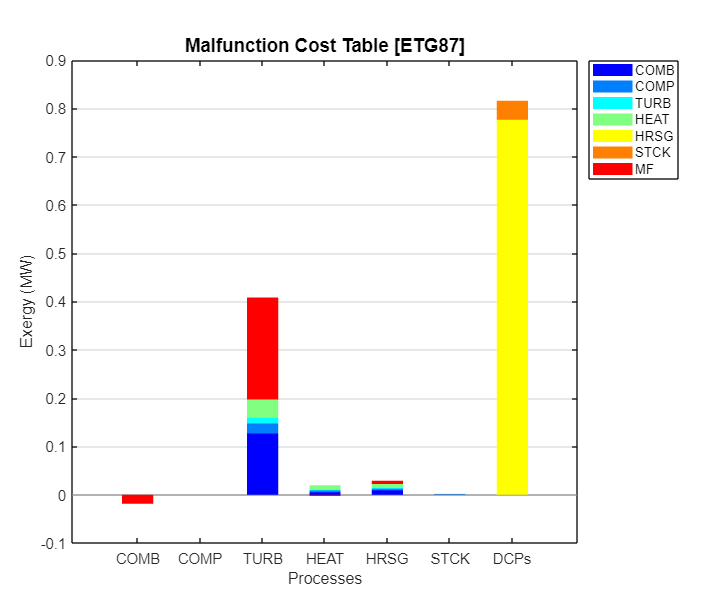

graphDiagnosis(res);